paramNameValStruct.SimulationMode = 'accelerator';
paramNameValStruct.TimeOut        = 40;
simOut = sim('exp2M_CSVposRef',paramNameValStruct);

simOut.getSimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2022-02-14 10:11:09'
           WallClockTimestampStop: '2022-02-14 10:11:52'
    InitializationElapsedWallTime: 2.2231
         ExecutionElapsedWallTime: 40.0198
       TerminationElapsedWallTime: 1.0805
             TotalElapsedWallTime: 43.3234
                     ProfilerData: 'Profiler is not enabled'


p1 = simOut.p1;
Ts = simOut.tout(2);
% create iddata type with inputs and outputs
data1 = iddata(p1.Data(:,2),p1.Data(:,1),Ts,'Name','Motor 1 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 2 poles and no zero
m11 = tfest(data1,2,0); m11.Report.Fit

ans = struct with fields:
    FitPercent: 93.8261
       LossFcn: 7.5279
           MSE: 7.5278
           FPE: 7.5677
           AIC: 9.2082e+03
          AICc: 9.2082e+03
          nAIC: 2.0239
           BIC: 9.2359e+03


% transfer function estimation with 1 pole and no zero
m12 = tfest(data1,1,0); m12.Report.Fit

ans = struct with fields:
    FitPercent: -17.0316
       LossFcn: 2.7052e+03
           MSE: 2.7049e+03
           FPE: 2.7135e+03
           AIC: 2.0349e+04
          AICc: 2.0349e+04
          nAIC: 7.9060
           BIC: 2.0366e+04


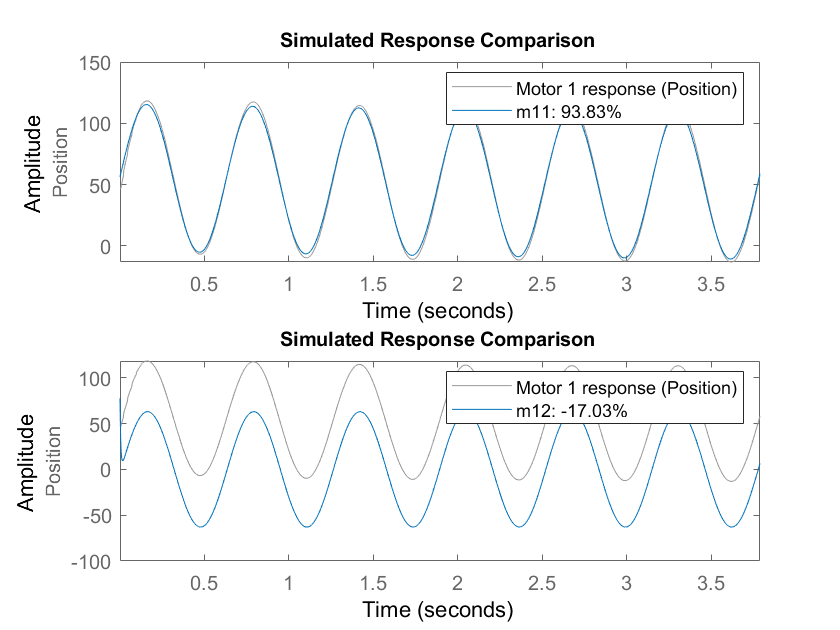

figure
subplot(2,1,1)
compare(data1,m11) % first order model evaluation
subplot(2,1,2)
compare(data1,m12) % second order model evaluation

p2 = simOut.p2;
data2 = iddata(p2.Data(:,2),p2.Data(:,1),Ts,'Name','Motor 2 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 2 poles and no zero
m21 = tfest(data2,2,0); m21.Report.Fit

ans = struct with fields:
    FitPercent: 97.0034
       LossFcn: 2.0099
           MSE: 1.7730
           FPE: 1.7824
           AIC: 6.4695e+03
          AICc: 6.4696e+03
          nAIC: 0.5779
           BIC: 6.4973e+03


% transfer function estimation with 1 pole and no zero
m22 = tfest(data2,1,0); m22.Report.Fit

ans = struct with fields:
    FitPercent: 86.8410
       LossFcn: 34.1891
           MSE: 34.1891
           FPE: 34.2975
           AIC: 1.2070e+04
          AICc: 1.2070e+04
          nAIC: 3.5351
           BIC: 1.2087e+04


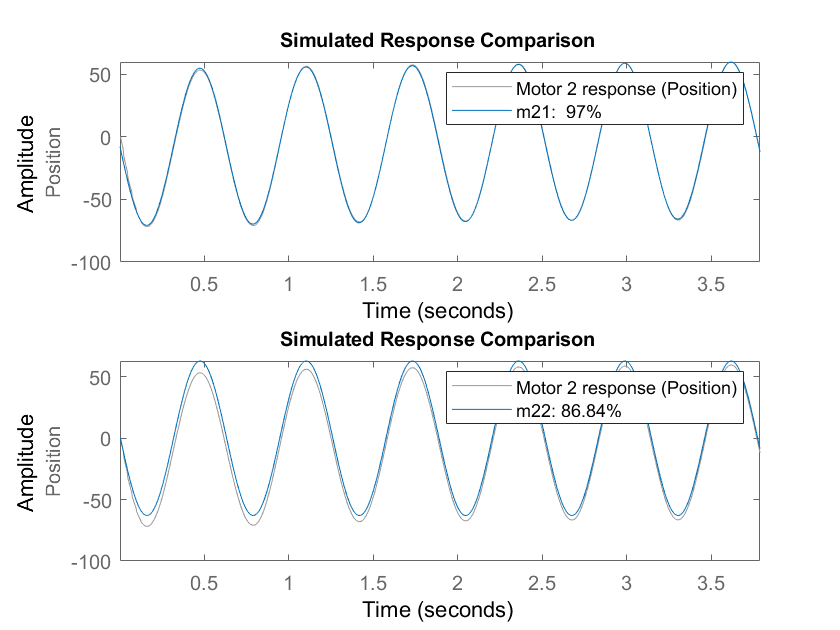

figure
subplot(2,1,1)
compare(data2,m21) % first order model evaluation
subplot(2,1,2)
compare(data2,m22) % second order model evaluation

From the results above, the first order transfer function model has competitive performance compared to second order variation. The first order transfer functions also reduce computation complexity. Thus it provides faster response.

clear m11 m21 data1 data2 opts tabularData
save Data/Exoskeleton/motorModel p1 p2 m12 m22 Ts
model = 'tf2M_CSVposRef_ctrlDesign';
load_system(model)
setActiveConfigSet(model, 'systemIdentification');
save_system(model)
open(model)